G = Plant1_2d


G =
 
Process model with transfer function:  
                Kp                     
  G(s) = ----------------- * exp(-Td*s)
         (1+Tp1*s)(1+Tp2*s)            
                                       
         Kp = 1.989                    
        Tp1 = 25.578                   
        Tp2 = 290.57                   
         Td = 14.49                    
                                       
Parameterization:
    {'P2D'}
   Number of free coefficients: 4
   Use "getpvec", "getcov" for parameters and their uncertainties.

Status:                                     
Estimated using PROCEST on time domain data.
Fit to estimation data: 98.5%               
FPE: 1.462, MSE: 1.358                      
 
Model Properties



Kp = G.Kp

Kp = 1.9890

Tp1 = G.Tp1

Tp1 = 25.5777

Tp2 = G.Tp2

Tp2 = 290.5660

Tz = G.Tz

Tz = 0

Td = G.Td

Td = 14.4900


syms s t

u = 110 * heaviside(t - 170)

$$u = 110\,\mathrm{heaviside}\left(t-170\right)$$

U = laplace(u)

$$U = \frac{110\,{\mathrm{e}}^{-170\,s}}{s}$$


G = Kp * (Tz * s + 1.0) * exp(-Td * s) / ((Tp1 * s + 1.0) * (Tp2 * s + 1.0))

$$G = \frac{8957731552653137\,{\mathrm{e}}^{-\frac{1449\,s}{100}}}{4503599627370496\,\left(\frac{5111690862163133\,s}{17592186044416}+1\right)\,\left(\frac{3599747296736645\,s}{140737488355328}+1\right)}$$


pretty(G)

                      /   1449 s \
                   exp| - ------ | 8957731552653137
                      \     100  /
----------------------------------------------------------------------
/ 5111690862163133 s     \ / 3599747296736645 s     \
| ------------------ + 1 | | ------------------ + 1 | 4503599627370496
\   17592186044416       / \   140737488355328      /




Y = G * U

$$Y = \frac{492675235395922535\,{\mathrm{e}}^{-170\,s}\,{\mathrm{e}}^{-\frac{1449\,s}{100}}}{2251799813685248\,s\,\left(\frac{5111690862163133\,s}{17592186044416}+1\right)\,\left(\frac{3599747296736645\,s}{140737488355328}+1\right)}$$


y = ilaplace(Y)

$$y = \frac{492675235395922535\,\mathrm{heaviside}\left(t-\frac{18449}{100}\right)\,\left(\frac{3599747296736645\,{\mathrm{e}}^{\frac{649116480666861568}{89993682418416125}-\frac{140737488355328\,t}{3599747296736645}}}{37293779600568419}-\frac{40893526897305064\,{\mathrm{e}}^{\frac{81139560083357696}{127792271554078325}-\frac{17592186044416\,t}{5111690862163133}}}{37293779600568419}+1\right)}{2251799813685248}$$


pretty(y)

                       /    / 649116480666861568   140737488355328 t \                       /  81139560083357696   17592186044416 t \                       \
                       | exp| ------------------ - ----------------- | 3599747296736645   exp| ------------------ - ---------------- | 40893526897305064     |
         /     18449 \ |    \  89993682418416125    3599747296736645 /                       \ 127792271554078325   5111690862163133 /                       |
heaviside| t - ----- | | -------------------------------------------------------------- - -------------------------------------------------------------- + 1 | 492675235395922535
         \      100  / \                        37293779600568419                                                37293779600568419                           /
---------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
        

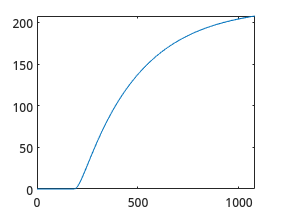


fplot(y, [0, 1080])